## **Section 1: *****Feeling the data***

### **Load the data**

load data_country

%extract every col (feature) in variables
%health factors
child_mort = Countrydata(:,1);
health = Countrydata(:,3);
life_exp = Countrydata(:,7);
fertility = Countrydata(:,8);

%socioeconomic factors
exports = Countrydata(:,2);
imports = Countrydata(:,4);
income = Countrydata(:,5);
inflation = Countrydata(:,6);
gdpp = Countrydata(:,9);

**Determine the type of every column**

class(child_mort) %child mortality

ans = 'double'

class(health) %health

ans = 'double'

class(life_exp) %life expectancy

ans = 'double'

class(fertility) %total fertility

ans = 'double'


class(exports) %exports

ans = 'double'

class(imports) %imports

ans = 'double'

class(income) %income

ans = 'double'

class(inflation) %inflation

ans = 'double'

class(gdpp) %GDPP

ans = 'double'

**Determine the range of values for every feature**

%range = max - min
mins = min(Countrydata);
maxs = max(Countrydata);
range = max(Countrydata) - min(Countrydata);

**See the statistics of the data (mean, stdv)**

means = mean(Countrydata);
stdv = std(Countrydata);

**Create the hist for each feature to see its distribution**

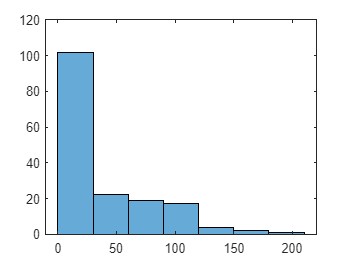

figure(1), histogram(Countrydata(:,1))

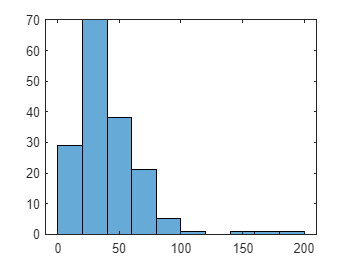

figure(2),histogram(Countrydata(:,2))

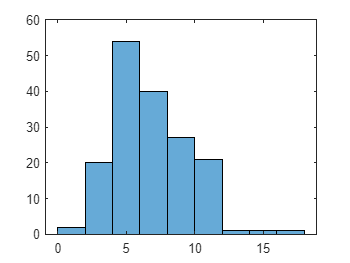

figure(3),histogram(Countrydata(:,3))

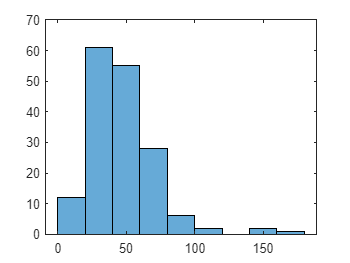

figure(4),histogram(Countrydata(:,4))

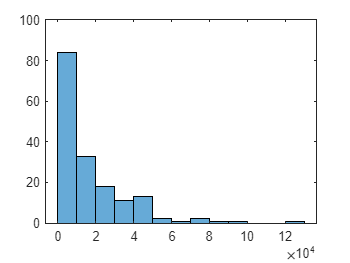

figure(5),histogram(Countrydata(:,5))

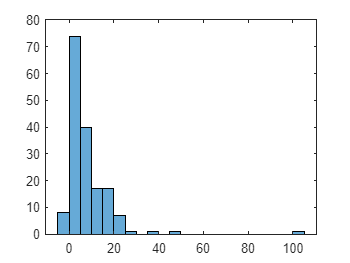

figure(6),histogram(Countrydata(:,6))

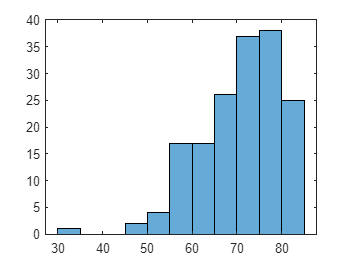

figure(7),histogram(Countrydata(:,7))

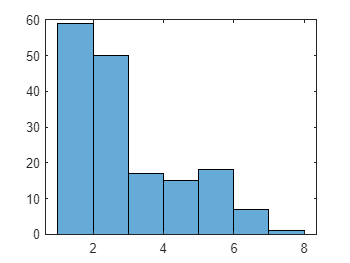

figure(8),histogram(Countrydata(:,8))

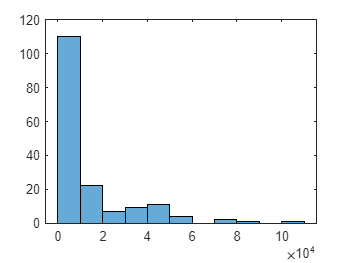

figure(9),histogram(Countrydata(:,9))

### Standarization

**Boxplots to see if there are outliers**

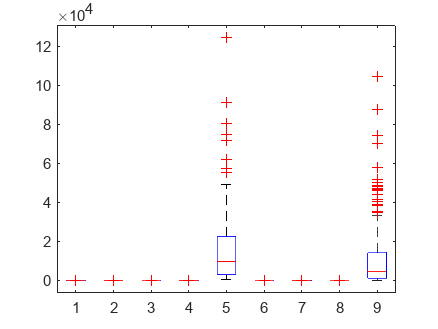

boxplot(Countrydata)

**Compute corr coeff to see linear dependance of each feature**

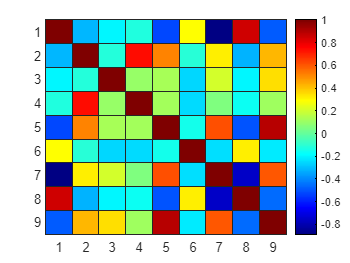

cor = corrcoef(Countrydata);
heatmap(cor)
colormap jet

**Standard score normalization**

features = [child_mort,exports,health,imports,income,inflation,life_exp,fertility,gdpp];
zscored_features = zscore(features);

### **Min-Max with standard score normalization**

normalized_features = (zscored_features - min(zscored_features)) ./ (max(zscored_features) - min(zscored_features));

### Min Max without standard score normalization

minmax_only = (features - min(features)) ./ (max(features) - min(features));

**Frame with all features scaled with standard score and min max**

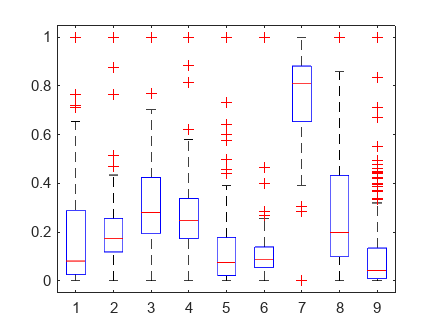

new_corr_coeff = corrcoef(normalized_features);
boxplot(normalized_features)

**Heatmap for the normalized features**

heatmap(new_corr_coeff)
colormap jet

**Box-plot features only with standard score**

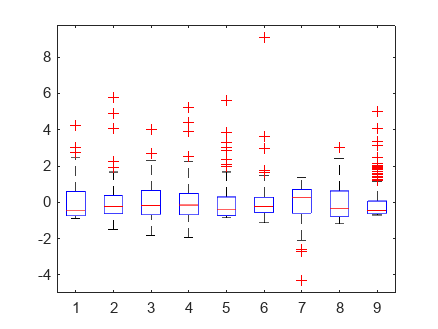

boxplot(zscored_features)

**Box-plots only with min max normalization**

boxplot(minmax_only)

## Section 2: *Clustering experiments*

## **1. First Kmeans experiment (all features included)**

### ELBOW to determine the number of clusters

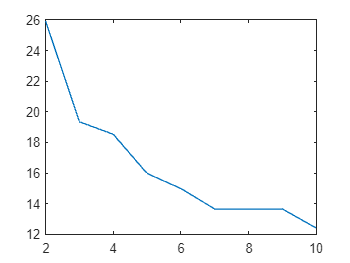

final = transpose(normalized_features);
%elbow
% Compute J_m and plot J_m versus m
[l,N]= size(final);
nruns=10;
m_min=2;
m_max=10;
J_m=[];
for m=m_min:m_max
    J_temp_min=inf;
    for t=1:nruns
        rand('seed',100*t)
        theta_ini=rand(l,m);
        [theta,bel,J]= k_means(final,theta_ini);
        if(J_temp_min>J)
            J_temp_min=J;
        end
    end
    J_m=[J_m J_temp_min];
end
m=m_min:m_max;
figure(2), plot(m,J_m)

### **K-means (3 clusters)**

k = 3;  
% we can use also the functions 'distant_init' and 'rand_init'
% to initialize the thetas
theta_ini = rand_data_init(final, k);
[theta,bel,J]=k_means(final,theta_ini);

### Plot features combinations

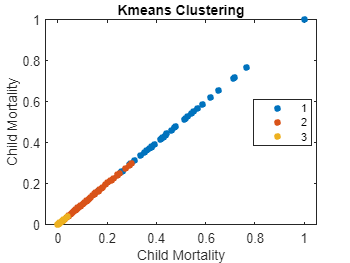

figure
gscatter(final(1,:), final(1,:), bel) 
xlabel('Child Mortality') 
ylabel('Child Mortality') 
title('Kmeans Clustering')

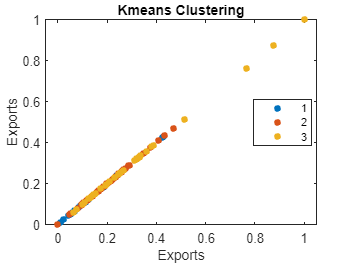

figure
gscatter(final(2,:), final(2,:), bel) 
xlabel('Exports') 
ylabel('Exports') 
title('Kmeans Clustering')

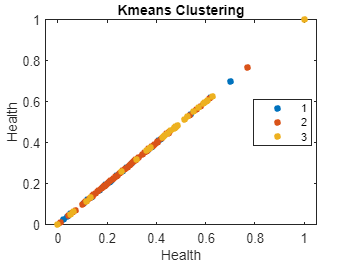

figure
gscatter(final(3,:), final(3,:), bel) 
xlabel('Health') 
ylabel('Health') 
title('Kmeans Clustering')

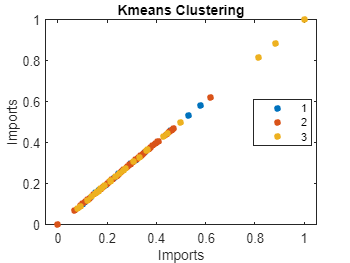

figure
gscatter(final(4,:), final(4,:), bel) 
xlabel('Imports') 
ylabel('Imports') 
title('Kmeans Clustering')

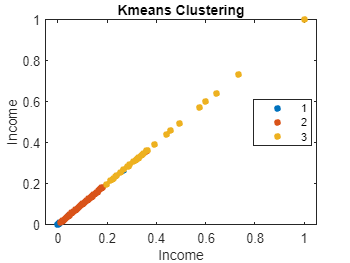

figure
gscatter(final(5,:), final(5,:), bel) 
xlabel('Income') 
ylabel('Income') 
title('Kmeans Clustering')

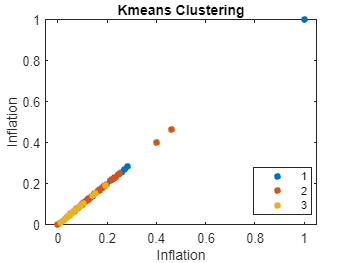

figure
gscatter(final(6,:), final(6,:), bel) 
xlabel('Inflation') 
ylabel('Inflation') 
title('Kmeans Clustering')

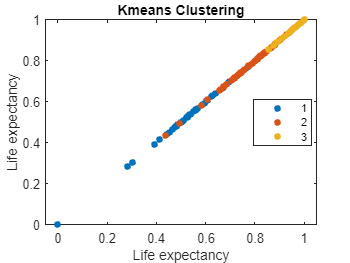

figure
gscatter(final(7,:), final(7,:), bel) 
xlabel('Life expectancy') 
ylabel('Life expectancy') 
title('Kmeans Clustering')

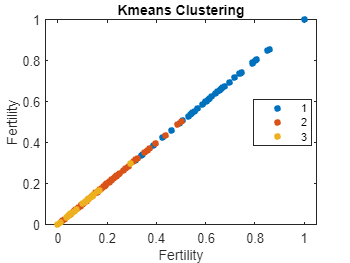

figure
gscatter(final(8,:), final(8,:), bel) 
xlabel('Fertility') 
ylabel('Fertility') 
title('Kmeans Clustering')

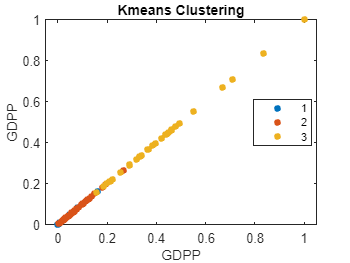

figure
gscatter(final(9,:), final(9,:), bel) 
xlabel('GDPP') 
ylabel('GDPP') 
title('Kmeans Clustering')

## 2. Second Kmeans experiment 

#### Features used: - Child mortality

####                            - Income 

####                            -  Life expectancy

####                             - Fertility

####                             - GDPP

**New frame with the above 5 features **

new_features= [normalized_features(:,1),normalized_features(:,5),normalized_features(:,7:9)];

### ELBOW to determine the number of clusters

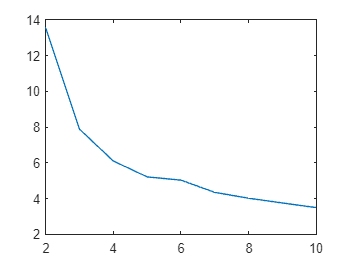

final = transpose(new_features);
%elbow
% Compute J_m and plot J_m versus m
[l,N]= size(final);
nruns=10;
m_min=2;
m_max=10;
J_m=[];
for m=m_min:m_max
    J_temp_min=inf;
    for t=1:nruns
        rand('seed',100*t)
        theta_ini=rand(l,m);
        [theta,bel,J]= k_means(final,theta_ini);
        if(J_temp_min>J)
            J_temp_min=J;
        end
    end
    J_m=[J_m J_temp_min];
end
m=m_min:m_max;
figure(2), plot(m,J_m)

**K-means (3 clusters)**

k = 3;  

% we can also use one of the functions 'rand_init' and 'distant_init'
% to initialize the thetas
theta_ini = rand_data_init(final, k);
[theta,bel,J]=k_means(final,theta_ini);

### **Plot Results**

### **1.**

%colors = [1 0 0; 0 1 0; 0 0 1];
%colors = [0 0 1;0 1 0; 1 0 0 ];
gscatter(final(2,:), final(4,:), bel,colors)

Unrecognized function or variable 'colors'.

xlabel('Income')
ylabel('Fertility') 
title('Kmeans(initialization with rand init)')
%legend('Highly Developed','Medium Developed','Less Developed','Location','northeast')

colormap([1 0 0; 0 0 0; 0 1 0; 0.5 0 0.5])
scatter3(final(5,:), final(1,:),final(4,:),'CData',bel)
xlabel('GDPP')
ylabel('child mortality')
zlabel('fertility')

### PLOT Results 

### 2D plots 

colors = [0 0 1; 1 0 0; 0 1 0];

figure
gscatter(final(1,:), final(2,:), bel,colors) 
xlabel('Child Mortality') 
ylabel('Income') 
title('Kmeans Clustering')
legend('Medium Developed','Less Developed','Highly Developed','Location','northeast')

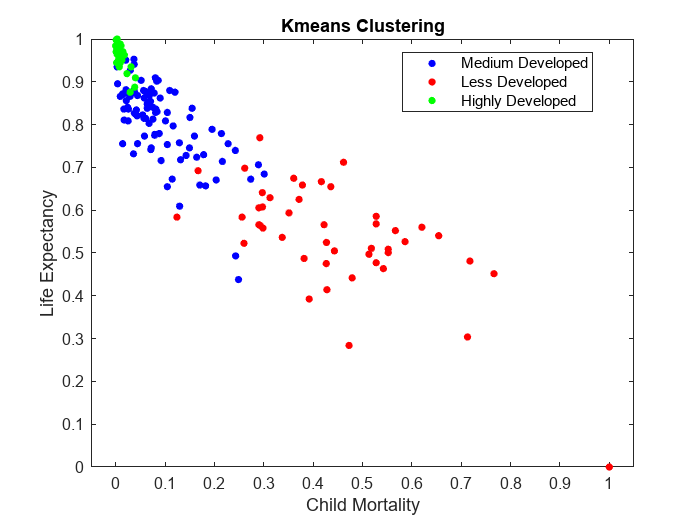

figure
gscatter(final(1,:), final(3,:), bel,colors) 
xlabel('Child Mortality') 
ylabel('Life Expectancy')
title('Kmeans Clustering')
legend('Medium Developed','Less Developed','Highly Developed')

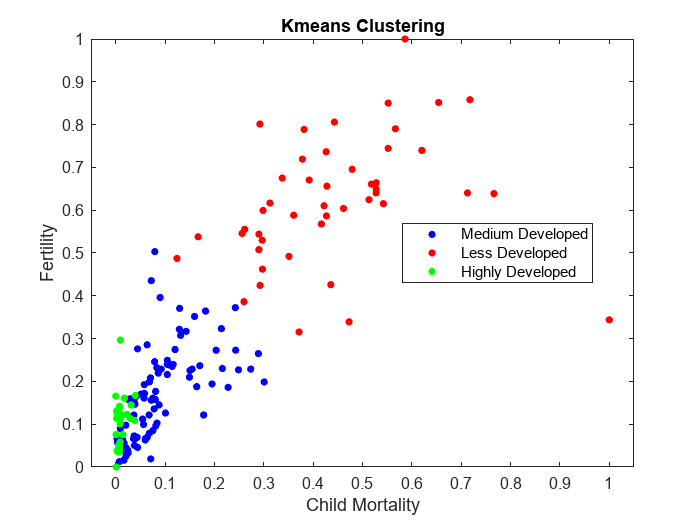

figure
gscatter(final(1,:), final(4,:), bel,colors) 
xlabel('Child Mortality') 
ylabel('Fertility')
title('Kmeans Clustering')
legend('Medium Developed','Less Developed','Highly Developed')

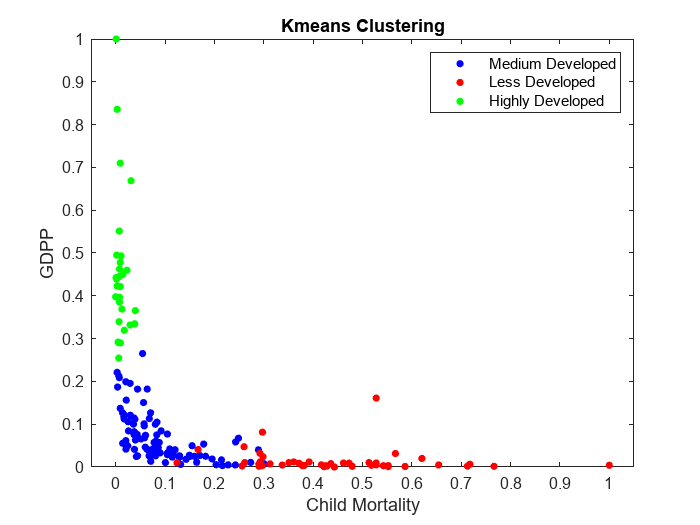

figure
gscatter(final(1,:), final(5,:), bel,colors) 
xlabel('Child Mortality') 
ylabel('GDPP')
title('Kmeans Clustering')
legend('Medium Developed','Less Developed','Highly Developed','Location','northeast')

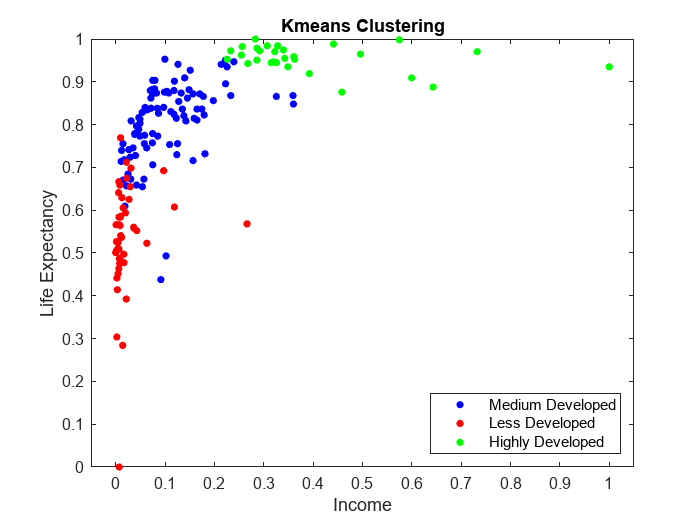

figure
gscatter(final(2,:), final(3,:), bel,colors) 
xlabel('Income') 
ylabel('Life Expectancy')
title('Kmeans Clustering')
legend('Medium Developed','Less Developed','Highly Developed','Location','southeast')

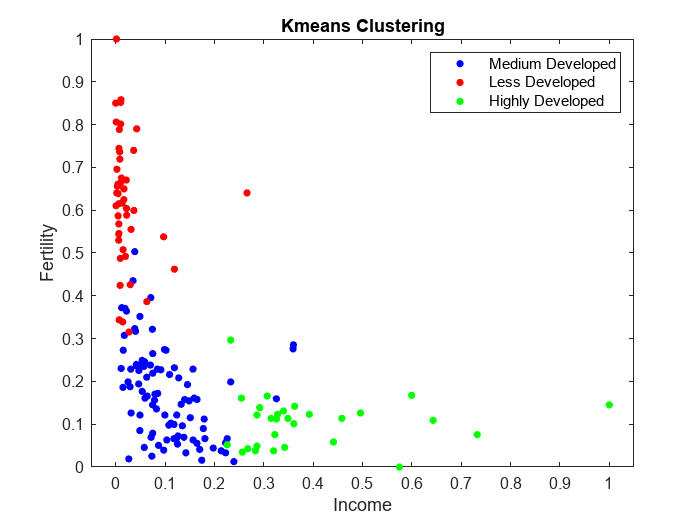

figure
gscatter(final(2,:), final(4,:), bel,colors) 
xlabel('Income') 
ylabel('Fertility')
title('Kmeans Clustering')
legend('Medium Developed','Less Developed','Highly Developed','Location','northeast')

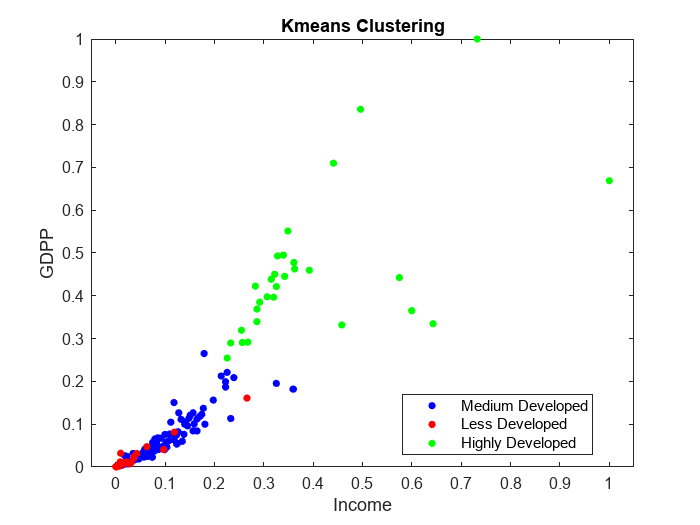

figure
gscatter(final(2,:), final(5,:), bel,colors) 
xlabel('Income') 
ylabel('GDPP')
title('Kmeans Clustering')
legend('Medium Developed','Less Developed','Highly Developed')

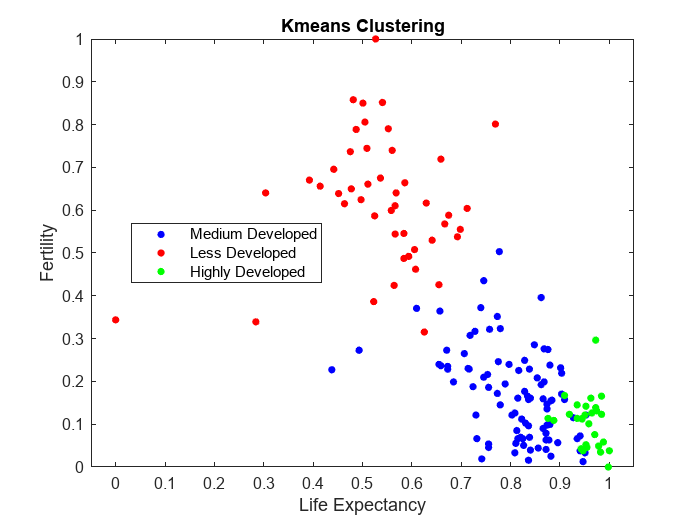

figure
gscatter(final(3,:), final(4,:), bel,colors) 
xlabel('Life Expectancy') 
ylabel('Fertility')
title('Kmeans Clustering')
legend('Medium Developed','Less Developed','Highly Developed')

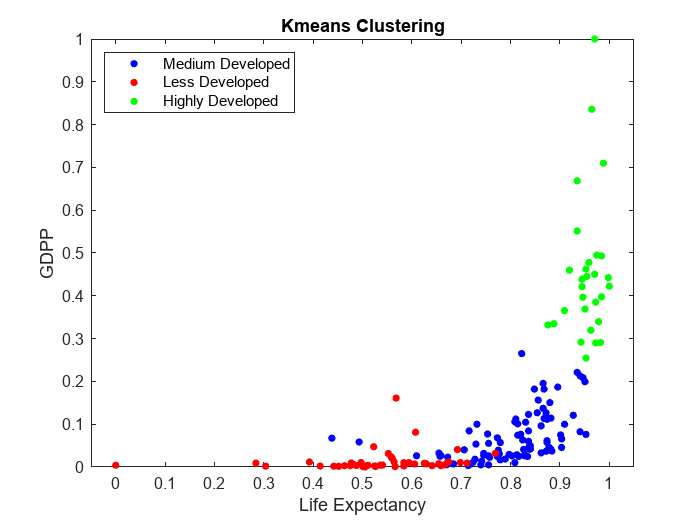

figure
gscatter(final(3,:), final(5,:), bel,colors) 
xlabel('Life Expectancy') 
ylabel('GDPP')
title('Kmeans Clustering')
legend('Medium Developed','Less Developed','Highly Developed','Location','northwest')

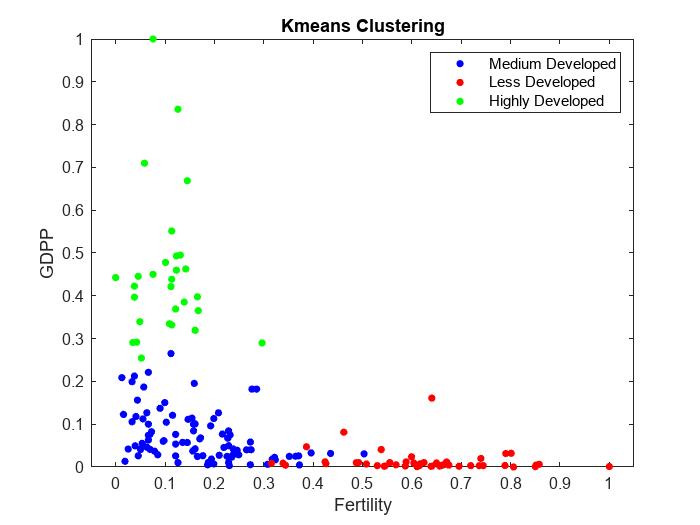

figure
gscatter(final(4,:), final(5,:), bel,colors) 
xlabel('Fertility') 
ylabel('GDPP')
title('Kmeans Clustering')
legend('Medium Developed','Less Developed','Highly Developed','Location','northeast')

## 3. Kmedians experiment

#### Features used: - Child mortality

####                            - Income 

####                            -  Life expectancy

####                             - Fertility

####                             - GDPP

### Elbow

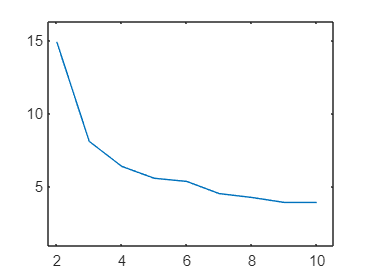

%elbow
% Compute J_m and plot J_m versus m
[l,N]= size(final);
nruns=10;
m_min=2;
m_max=10;
J_m=[];
for m=m_min:m_max
    J_temp_min=inf;
    for t=1:nruns
        rand('seed',100*t)
        theta_ini=rand(l,m);
        [theta,bel,J]= k_medians(final,theta_ini);
        if(J_temp_min>J)
            J_temp_min=J;
        end
    end 
    J_m=[J_m J_temp_min];
end
m=m_min:m_max;
figure(2), plot(m,J_m)

### Kmedians

k = 3;
% we can also use the functions 'rand_init' and 'distant_init'
% to initialize the thetas
theta_ini = rand_data_init(final, k);
[theta,bel,J]=k_medians(final,theta_ini);

### Plot Results

#### 1.

gscatter(final(1,:), final(4,:), bel)
xlabel('Child mortality') 
ylabel('Fertility')
title('Kmedians')
legend('Medium Developed','Less Developed','Highly Developed','Location','southeast')

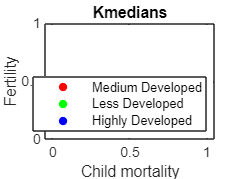

colormap([1 0 0; 0 1 0; 0 0 1])

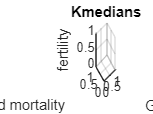

scatter3(final(5,:), final(1,:),final(4,:),'CData',bel)
xlabel('GDPP')
ylabel('child mortality')
zlabel('fertility')
title('Kmedians')

#### 2.

gscatter(final(2,:), final(4,:), bel)
xlabel('Income') 
ylabel('Fertility') 
title('Kmedians')
legend('Medium Developed','Less Developed','Highly Developed','Location','northeast')

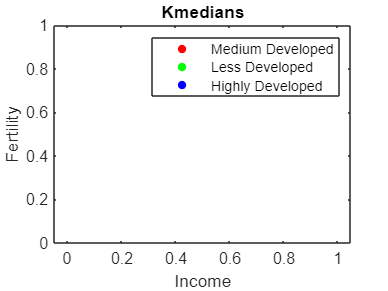

colormap([1 0 0; 0 1 0; 0 0 1])

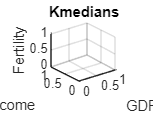

scatter3(final(5,:), final(2,:),final(4,:),'CData',bel)
xlabel('GDPP')
ylabel('Income')
zlabel('Fertility')
title('Kmedians')

## 4. Kmedoids experiment

#### Features used: - Child mortality

####                            - Income 

####                            -  Life expectancy

####                             - Fertility

####                             - GDPP

### Elbow

%elbow
% Compute J_m and plot J_m versus m
[l,N]= size(final);
nruns=5;
m_min=2;
m_max=7;
J_m=[];
for m=m_min:m_max
    J_temp_min=inf;
    for t=1:nruns
        rand('seed',100*t)
        theta_ini=rand(l,m);
        [bel,cost,w,a]= k_medoids(final,m,0);
        if(J_temp_min>J)
            J_temp_min=J;
        end
    end 
    J_m=[J_m J_temp_min];
end
m=m_min:m_max;
figure(2), plot(m,J_m)

### Kmedoids

k = 3;
[bel,cost,w,a]=k_medoids(final,k,0);

### Plot Results

#### 1.

colors = [0 1 0; 0 0 1; 1 0 0];
gscatter(final(1,:), final(4,:), bel,colors)
xlabel('Child mortality')
ylabel('Fertility') 
title('Kmedoids')
legend('Less Developed','Highly Developed','Medium Developed','Location','southeast')

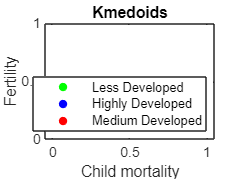

colormap([0 1 0; 0 0 1; 1 0 0])

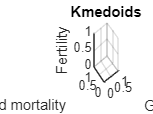

scatter3(final(5,:), final(1,:),final(4,:),'CData',bel)
xlabel('GDPP')
ylabel('Child mortality')
zlabel('Fertility')
title('Kmedoids')

#### 2.

colors = [0 1 0; 0 0 1; 1 0 0];
gscatter(final(2,:), final(4,:), bel,colors)
xlabel('Income') 
ylabel('Fertility') 
title('Kmedoids')
%legend('Less Developed','Highly Developed','Medium Developed','Location','northeast')

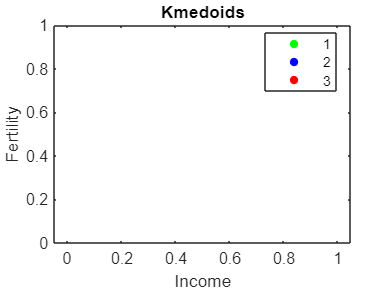

colormap([0 1 0; 0 0 1; 1 0 0])

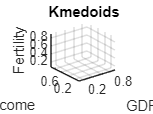

scatter3(final(5,:), final(2,:),final(4,:),'CData',bel)
xlabel('GDPP')
ylabel('Income')
zlabel('Fertility')
title('Kmedoids')

## Possibilistic kmeans

[U,theta]=possibi(final,3,[0.3,0.3,0.3],0,0,1,.001)

### Plot Results

#### 1.

2D

scatter(final(1,:), final(4,:), [], U, 'filled')
xlabel('Child Mortality')
ylabel('Fertility')
title('Possibilistic')

3D

%colormap([1 0 0; 0 0 0; 0 1 0; 0.5 0 0.5])
%scatter3(final(5,:), final(1,:),final(4,:),'CData',)
%xlabel('GDPP')
%ylabel('child mortality')
%zlabel('fertility')
%title('Possibilistic')

## **CLUSTERS CHARACTERIZATION**

%separate each cluster data
% Find the unique cluster labels
clusters = unique(bel);

% Initialize an empty cell array to store the data for each cluster
cluster_data = cell(length(clusters), 1);

% Loop over the clusters
for i = 1:length(clusters)
    % Extract the data for the current cluster
    cluster_data{i} = final(:, bel == clusters(i));
end
mean(cluster_data{1,1})

ans =     0.3878    0.3593    0.3151    0.3626    0.4025    0.3666    0.3099    0.3912    0.3628    0.3592    0.3418    0.2983    0.3709    0.3855    0.3603    0.3319    0.3492    0.4163    0.5559    0.2852    0.3815    0.3430    0.4851    0.3459    0.2823    0.5560    0.3479    0.4033    0.2902    0.2830    0.3140    0.3885    0.4414    0.3617    0.3480    0.3834


cluster_data1 = transpose(cluster_data{1,1})

cluster_data1 =     0.0107    0.3279    0.9842    0.1230    0.4932
    0.0083    0.3424    0.9546    0.0457    0.4454
    0.0292    0.3255    0.8659    0.1593    0.1954
    0.0093    0.3255    0.9448    0.1120    0.4216
    0.0385    0.6431    0.8876    0.1088    0.3347
    0.0146    0.3223    0.9704    0.0757    0.4502
    0.0049    0.2676    0.9428    0.0426    0.2918
    0.0073    0.3488    0.9349    0.1136    0.5514
    0.0019    0.3151    0.9448    0.1136    0.4388
    0.0078    0.2917    0.9724    0.1388    0.3853


cluster_data2 = transpose(cluster_data{2,1})

cluster_data2 =     0.4265    0.0080    0.4753    0.7366    0.0031
    0.5667    0.0425    0.5523    0.7902    0.0315
    0.5278    0.0097    0.5858    0.6640    0.0050
    0.5521    0.0066    0.5089    0.7445    0.0033
    0.4430    0.0012    0.5049    0.8060         0
    0.5131    0.0165    0.4970    0.6246    0.0103
    0.7128    0.0022    0.3037    0.6404    0.0021
    0.7176    0.0106    0.4813    0.8580    0.0064
    0.4167    0.0064    0.6667    0.5678    0.0051
    0.5521         0    0.5010    0.8502    0.0010


cluster_data3 = transpose(cluster_data{3,1})

cluster_data3 =     0.0682    0.0749    0.8718    0.0789    0.0368
    0.1203    0.0988    0.8757    0.2744    0.0404
    0.0375    0.1487    0.8817    0.1546    0.1142
    0.0579    0.1454    0.8619    0.1924    0.0961
    0.0755    0.0490    0.8126    0.0852    0.0285
    0.1782    0.1237    0.7298    0.1215    0.0535
    0.0545    0.1792    0.8225    0.1120    0.2650
    0.2278    0.0147    0.7554    0.1861    0.0050
    0.0565    0.1181    0.8797    0.0994    0.1505
    0.0141    0.1253    0.7554    0.0536    0.0554



mean_medium = mean(cluster_data{1,1});
mean_less = mean(cluster_data{2,1});
mean_highly = mean(cluster_data{3,1});

std_medium = std(cluster_data1);
std_less = std(cluster_data2);
std_highly = std(cluster_data3);
